# 802.11a OFDM TxRx

参考：https://zhuanlan.zhihu.com/p/57967971

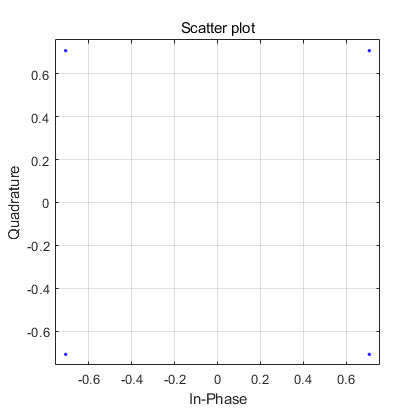

clc
clear

%% 参数设置
N_sc=52;      %系统子载波数（不包括直流载波）、number of subcarrier
N_fft=64;            % FFT 长度
N_cp=16;             % 循环前缀长度、Cyclic prefix
N_symbo=N_fft+N_cp;        % 1个完整OFDM符号长度
N_c=53;             % 包含直流载波的总的子载波数、number of carriers
M=4;               %4PSK调制
SNR=0:1:25;         %仿真信噪比
N_frm=10;            % 每种信噪比下的仿真帧数、frame
Nd=6;               % 每帧包含的OFDM符号数
P_f_inter=6;      %导频间隔
data_station=[];    %导频位置
L=7;                %卷积码约束长度
tblen=6*L;          %Viterbi译码器回溯深度
stage = 3;          % m序列的阶数
ptap1 = [1 3];      % m序列的寄存器连接方式
regi1 = [1 1 1];    % m序列的寄存器初始值

%% 基带数据数据产生
P_data=randi([0 1],1,N_sc*Nd*N_frm);

%% 信道编码（卷积码、或交织器）
%卷积码：前向纠错非线性码
%交织：使突发错误最大限度的分散化
trellis = poly2trellis(7,[133 171]);       %(2,1,7)卷积编码
code_data=convenc(P_data,trellis);

%% qpsk调制
data_temp1= reshape(code_data,log2(M),[])';             %以每组2比特进行分组，M=4
data_temp2= bi2de(data_temp1);                             %二进制转化为十进制
modu_data=pskmod(data_temp2,M,pi/M);              % 4PSK调制
% figure(1);
scatterplot(modu_data),grid;                  %星座图(也可以取实部用plot函数)


%% 扩频
%————————————————————————————————————————————————————————%
%扩频通信信号所占有的频带宽度远大于所传信息必需的最小带宽
%根据香农定理，扩频通信就是用宽带传输技术来换取信噪比上的好处，这就是扩频通信的基本思想和理论依据。
%扩频就是将一系列正交的码字与基带调制信号内积
%扩频后数字频率变成了原来的m倍。码片数量 = 2（符号数）* m（扩频系数）
%————————————————————————————————————————————————————————%

code = mseq(stage,ptap1,regi1,N_sc);     % 扩频码的生成
code = code * 2 - 1;         %将1、0变换为1、-1
modu_data=reshape(modu_data,N_sc,length(modu_data)/N_sc);
spread_data = spread(modu_data,code);        % 扩频
spread_data=reshape(spread_data,[],1);

%% 插入导频
P_f=3+3*1i;                       %Pilot frequency
P_f_station=[1:P_f_inter:N_fft];%导频位置（导频位置很重要，why?）
pilot_num=length(P_f_station);%导频数量

for img=1:N_fft                        %数据位置
    if mod(img,P_f_inter)~=1          %mod(a,b)就是求的是a除以b的余数
        data_station=[data_station,img];
    end
end
data_row=length(data_station);
data_col=ceil(length(spread_data)/data_row);

pilot_seq=ones(pilot_num,data_col)*P_f;%将导频放入矩阵
data=zeros(N_fft,data_col);%预设整个矩阵
data(P_f_station(1:end),:)=pilot_seq;%对pilot_seq按行取

if data_row*data_col>length(spread_data)
    data2=[spread_data;zeros(data_row*data_col-length(spread_data),1)];%将数据矩阵补齐，补0是虚载频~
end

%% 串并转换
data_seq=reshape(data2,data_row,data_col);
data(data_station(1:end),:)=data_seq;%将导频与数据合并

%% IFFT
ifft_data=ifft(data); 

%% 插入保护间隔、循环前缀
Tx_cd=[ifft_data(N_fft-N_cp+1:end,:);ifft_data];%把ifft的末尾N_cp个数补充到最前面

%% 并串转换
Tx_data=reshape(Tx_cd,[],1);%由于传输需要

%% 信道（通过多经瑞利信道、或信号经过AWGN信道）
 Ber=zeros(1,length(SNR));
 Ber2=zeros(1,length(SNR));
for jj=1:length(SNR)
    rx_channel=awgn(Tx_data,SNR(jj),'measured');%添加高斯白噪声
    
%% 串并转换
    Rx_data1=reshape(rx_channel,N_fft+N_cp,[]);
    
%% 去掉保护间隔、循环前缀
    Rx_data2=Rx_data1(N_cp+1:end,:);
%% FFT
    fft_data=fft(Rx_data2);
    
%% 信道估计与插值（均衡）
    data3=fft_data(1:N_fft,:); 
    Rx_pilot=data3(P_f_station(1:end),:); %接收到的导频
    h=Rx_pilot./pilot_seq; 
    H=interp1( P_f_station(1:end)',h,data_station(1:end)','linear','extrap');%分段线性插值：插值点处函数值由连接其最邻近的两侧点的线性函数预测。对超出已知点集的插值点用指定插值方法计算函数值

%% 信道校正
    data_aftereq=data3(data_station(1:end),:)./H;
%% 并串转换
    data_aftereq=reshape(data_aftereq,[],1);
    data_aftereq=data_aftereq(1:length(spread_data));
    data_aftereq=reshape(data_aftereq,N_sc,length(data_aftereq)/N_sc);
    
    
%% 解扩
    demspread_data = despread(data_aftereq,code);       % 数据解扩
    
%% QPSK解调
    demodulation_data=pskdemod(demspread_data,M,pi/M);    
    De_data1 = reshape(demodulation_data,[],1);
    De_data2 = de2bi(De_data1);
    De_Bit = reshape(De_data2',1,[]);

%% （解交织）
%% 信道译码（维特比译码）
    trellis = poly2trellis(7,[133 171]);
    rx_c_de = vitdec(De_Bit,trellis,tblen,'trunc','hard');   %硬判决

%% 计算误码率
    [err,Ber2(jj)] = biterr(De_Bit(1:length(code_data)),code_data);%译码前的误码率
    [err, Ber(jj)] = biterr(rx_c_de(1:length(P_data)),P_data);%译码后的误码率

end
 figure(2);
 semilogy(SNR,Ber2,'b-s');
 hold on;
 semilogy(SNR,Ber,'r-o');
 hold on;
 legend('4PSK调制、卷积码译码前（有扩频）','4PSK调制、卷积码译码后（有扩频）');
 hold on;
 xlabel('SNR');
 ylabel('BER');
 title('AWGN信道下误比特率曲线');   
 
 figure(3)
 subplot(2,1,1);
 x=0:1:30;
 stem(x,P_data(1:31));
 ylabel('amplitude');
 title('发送数据（以前30个数据为例)');
 legend('4PSK调制、卷积译码、有扩频');

 subplot(2,1,2);
 x=0:1:30;
 stem(x,rx_c_de(1:31));
 ylabel('amplitude');
 title('接收数据(以前30个数据为例)');
 legend('4PSK调制、卷积译码、有扩频');